R(1) = Link('d', 0.08, 'a', 0, 'alpha', -pi/2);
R(2) = Link('d', 0, 'a', -0.105, 'alpha', 0);
R(3) = Link('d', 0, 'a', 0.105, 'alpha', 0);
R(4) = Link('d', 0, 'a', 0, 'alpha', -pi/2);
Tool= [1 0 0 0; 0 1 0 0; 0 0 1 0.065; 0 0 0 1]; %Matriz Homog. herramienta
Offset = [0 pi/2 -pi/2 -pi/2]; 
World = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]; %A modificar cuando realizemos las aplicaciones.
PhantomII = SerialLink(R, 'name', 'PhantomII','tool',Tool,'offset',Offset,'base',World)

 
PhantomII = 
 
PhantomII:: 4 axis, RRRR, stdDH, slowRNE                         
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|       0.08|          0|    -1.5708|          0|
|  2|         q2|          0|     -0.105|          0|     1.5708|
|  3|         q3|          0|      0.105|          0|    -1.5708|
|  4|         q4|          0|          0|    -1.5708|    -1.5708|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, 0, 0.065), RPY/xyz = (0, 0, 0) deg              
 


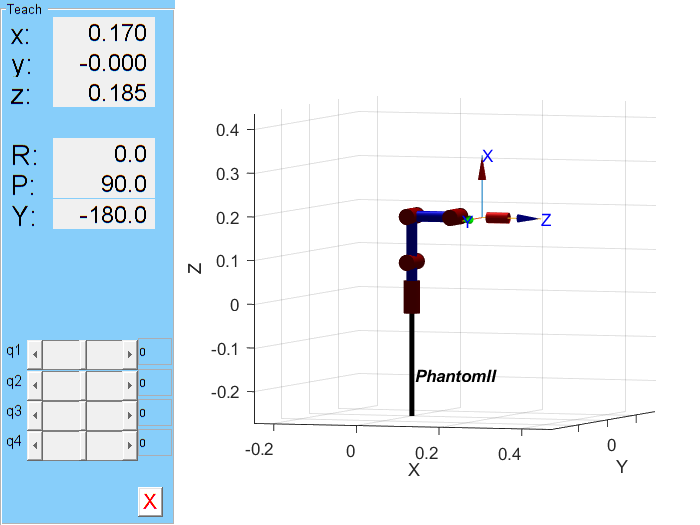

q = [0 0 0 0]; %Posición de reposo
PhantomII.plot(q); %Dibujamos el robot en la posición de reposo
PhantomII.teach();

H01=eye(4)*transl(0,0,0.08)*trotx(-90)

H01 =     1.0000         0         0         0
         0         0    1.0000         0
         0   -1.0000         0    0.0800
         0         0         0    1.0000


H02=H01*transl(0,-0.105,0)*trotz(90)

H02 =          0   -1.0000         0         0
         0         0    1.0000         0
   -1.0000         0         0    0.1850
         0         0         0    1.0000


H03=H02*transl(0,-0.105,0)*trotz(-90)

H03 =     1.0000         0         0    0.1050
         0         0    1.0000         0
         0   -1.0000         0    0.1850
         0         0         0    1.0000


H0TCP=H03*transl(0.065,0,0)*troty(90)*trotz(-90)

H0TCP =          0         0    1.0000    0.1700
         0   -1.0000         0         0
    1.0000         0         0    0.1850
         0         0         0    1.0000


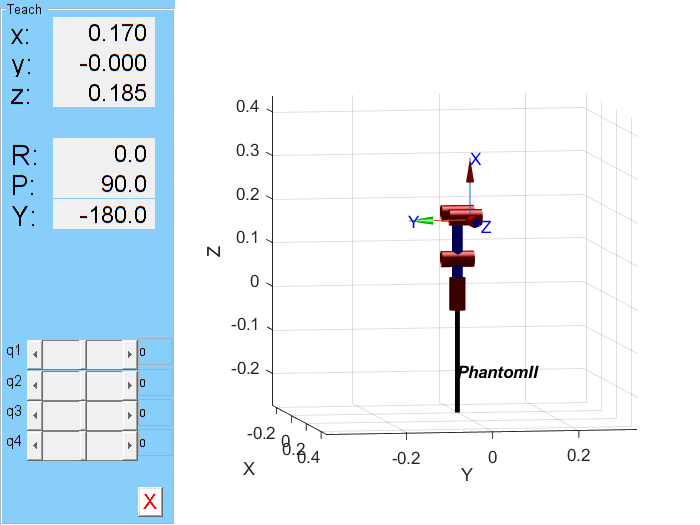

%Poses robot
%Home
qhome = [0 0 0 0]; %Posición de reposo
PhantomII.plot(qhome)

q1=[25 25 20 -20]*(pi/180)

q1 =     0.4363    0.4363    0.3491   -0.3491


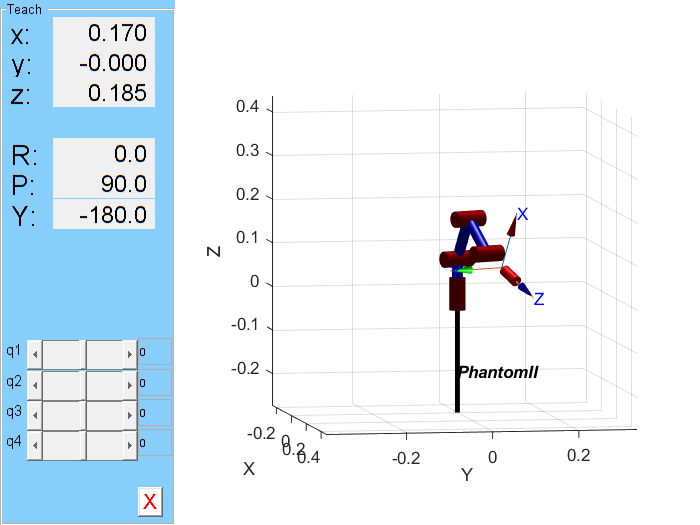

PhantomII.plot(q1)

q2=[-35 35 -30 30]*(pi/180)

q2 =    -0.6109    0.6109   -0.5236    0.5236


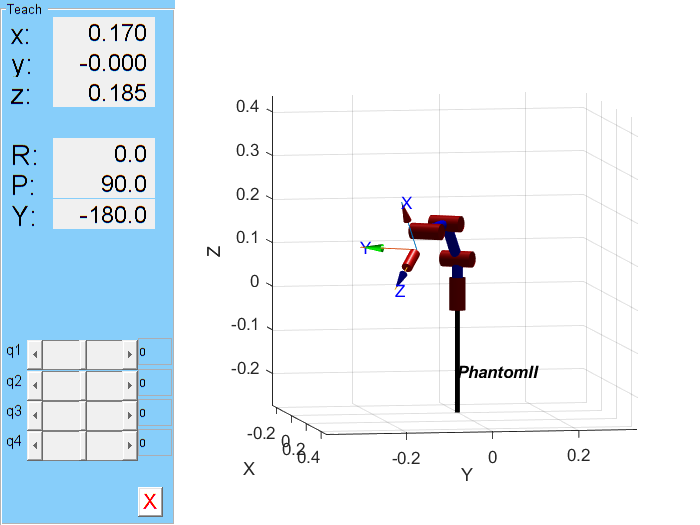

PhantomII.plot(q2)

q3=[85 -20 55 25]*(pi/180)

q3 =     1.4835   -0.3491    0.9599    0.4363


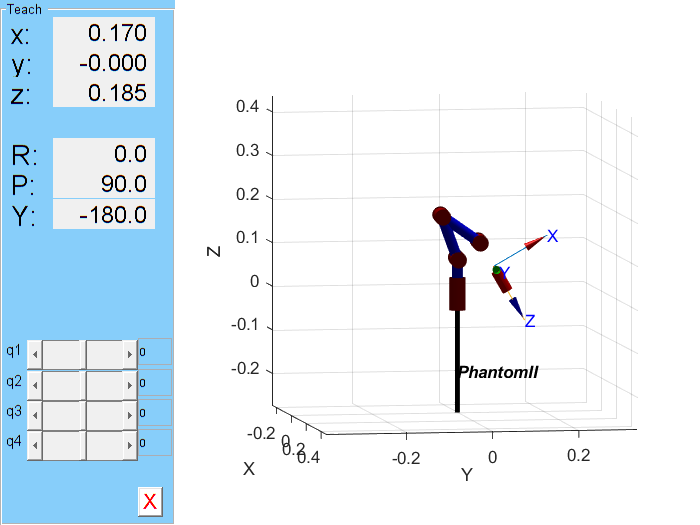

PhantomII.plot(q3)

q4=[80 -35 55 -45]*(pi/180)

q4 =     1.3963   -0.6109    0.9599   -0.7854


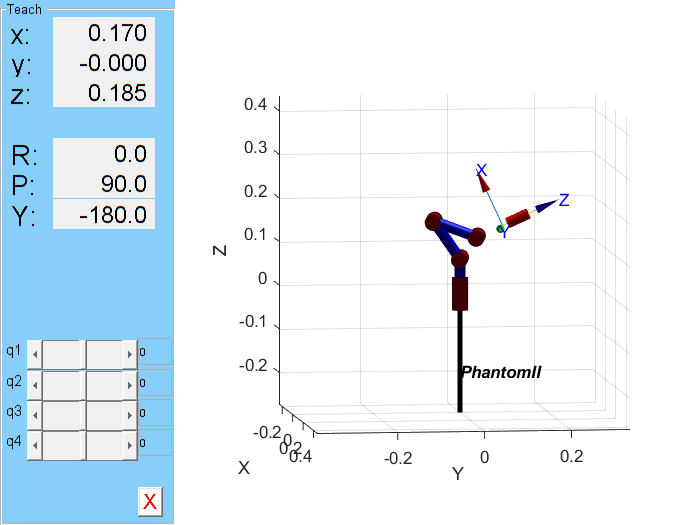

PhantomII.plot(q4)